# TPA 3 MPC Grupo 10

A contiunación se obtiene el modelo discrete en espacio de estados a partir del modelo de orden 6 obtenido en el TP1 (identificación)

close all; clc;
s = tf('s');

% modelo de orden 6
model_6 = 1.261e06/(s^6 + 75.11* s^5 + 1869* s^4 + 2.523e04* s^3 + 1.888e05* s^2 + 7.568e05* s + 1.26e06)


model_6 =
 
                                  1.261e06
  ------------------------------------------------------------------------
  s^6 + 75.11 s^5 + 1869 s^4 + 25230 s^3 + 188800 s^2 + 756800 s + 1.26e06
 
Continuous-time transfer function.
Model Properties



% TIEMPO DE MUESTREO
Ts = 0.1;

model_discrete = c2d(model_6, Ts)


model_discrete =
 
  0.0006481 z^5 + 0.0149 z^4 + 0.0314 z^3 + 0.01172 z^2 + 0.0007133 z + 3.173e-06
  -------------------------------------------------------------------------------
    z^6 - 2.286 z^5 + 2.205 z^4 - 1.148 z^3 + 0.3332 z^2 - 0.04562 z + 0.000547
 
Sample time: 0.1 seconds
Discrete-time transfer function.
Model Properties


[model_A, model_B, model_C, model_D] = tf2ss(model_discrete.Numerator{1}, model_discrete.Denominator{1});

Ahora se obtiene el modelo en espacio de estados pero considerando variaciones en la entrada en de las muestras $\Delta U$(modelo incremental = inc_model)

A_expanded = [model_A, model_B; zeros(1, length(model_A)), ones(1, 1)];
B_expanded = [model_B; ones(1, 1)];
C_expanded = [model_C, zeros(1,1)];

inc_model = ss(A_expanded, B_expanded, C_expanded, 0, Ts)


inc_model =
 
  A = 
              x1         x2         x3         x4         x5         x6         x7
   x1      2.286     -2.205      1.148    -0.3332    0.04562  -0.000547          1
   x2          1          0          0          0          0          0          0
   x3          0          1          0          0          0          0          0
   x4          0          0          1          0          0          0          0
   x5          0          0          0          1          0          0          0
   x6          0          0          0          0          1          0          0
   x7          0          0          0          0          0          0          1
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
   x4   0
   x5   0
   x6   0
   x7   1
 
  C = 
              x1         x2         x3         x4         x5         x6         x7
   y1  0.0006481     0.0149     0.0314    0.01172  0.0007133  3.173e-06          0
 
  D = 
       u1
   y1   0
 
Sample time: 0.1 se

Se cargan las matrices F y $\phi \;$

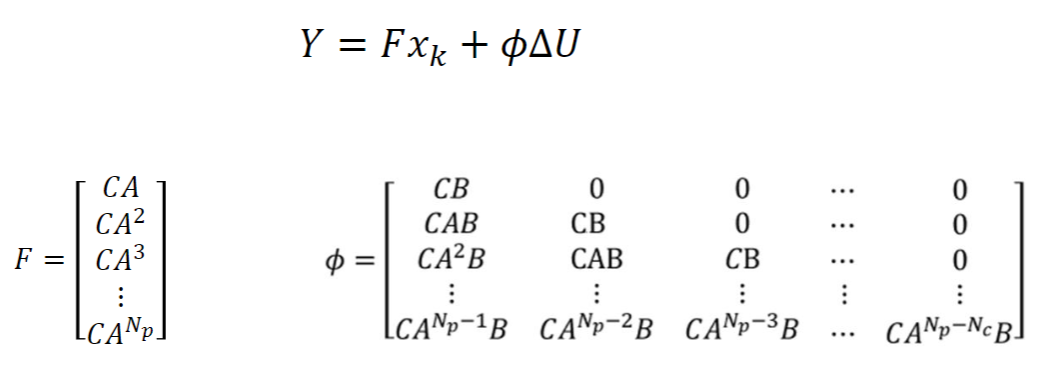

## Para calcular Np consideré que si Ts=0.1 y Tr=1.4 entonces entran 14 muestras hasta que se extinguen los transitorios

# IMPORTANTE: No se si lo anterior es cierto

Np = 15;
Nc = 1;

% Esto genera F para un rango dinámico Np
F_mat = zeros(Np, length(A_expanded));
F_mat(1, :) = C_expanded*A_expanded;
for i = 2:Np
    F_mat(i, :) = F_mat(i-1, :)*A_expanded;
end
F_mat

F_mat =     0.0164    0.0300    0.0125    0.0005    0.0000   -0.0000    0.0006
    0.0674   -0.0237    0.0193   -0.0054    0.0007   -0.0000    0.0170
    0.1305   -0.1294    0.0720   -0.0217    0.0031   -0.0000    0.0845
    0.1689   -0.2158    0.1280   -0.0404    0.0059   -0.0001    0.2149
    0.1704   -0.2444    0.1535   -0.0504    0.0076   -0.0001    0.3839
    0.1452   -0.2223    0.1452   -0.0492    0.0077   -0.0001    0.5543
    0.1095   -0.1749    0.1175   -0.0407    0.0065   -0.0001    0.6994
    0.0756   -0.1241    0.0850   -0.0300    0.0049   -0.0001    0.8090
    0.0486   -0.0816    0.0567   -0.0203    0.0034   -0.0000    0.8846
    0.0296   -0.0505    0.0356   -0.0128    0.0022   -0.0000    0.9332



% Esto genera phi para un rango dinámico de Np y Nc
phi_mat = zeros(Np, Nc);
for j = 1:Nc
    for i = 1:Np
        if (i < j)
            phi_mat(i, j) = 0;
        elif (i == j)
            phi_mat(i, j) = C_expanded*B_expanded;
        else
            phi_mat(i, j) = C_expanded*(A_expanded^(Np-j))*B_expanded;
        end
    end
end
phi_mat

phi_mat =     0.9975
    0.9975
    0.9975
    0.9975
    0.9975
    0.9975
    0.9975
    0.9975
    0.9975
    0.9975
